clc;clear;close all;

%% GLOBAL CONSTANTS: SET BEFORE RUNNING %%
x_max = 200; y_max = 200;
x_min = 0; y_min = 0;
x_start = 20; y_start = 50; theta_start = 0;
x_goal = 81; y_goal = 55; theta_goal = 90*pi/180;
l_car = 7.5; w_car = 3;
parking_spot_to_car_ratio = 2.4;
max_iter = 2000;
bias = 0.05;
angle_weighting = 5;

numofpathfound = 0;

obstacle1 = [35 45 10 35];
obstacle2 = [40 10 20 15];


%define parking spot based on above constants
parking_width = w_car*parking_spot_to_car_ratio;
parking_length = l_car*parking_spot_to_car_ratio;
thres_radius = parking_width*1.5;
X0 = x_goal - parking_width/2; 
X1 = x_goal + parking_width/2;
Y0 = y_goal - parking_length/2;
Y1 = y_goal + parking_length/2;

Y3 = y_goal - 1.5*parking_length;
obstacle3 = [X0 Y1 parking_width parking_length];  %parallel parking spot above
obstacle4 = [X0 Y3 parking_width parking_length];  %parallel parking spot below       
X2 = x_goal - 1.5*w_car*parking_spot_to_car_ratio;
obstacle5 = [X2 Y3 parking_width 3*parking_length];  %wall on left

th_max = 2*pi();
flag_success = 0;
flag_near_goal = 0;
goal = 0;
%non-holonomic values
dt = 0.1;
v_range_far = 1:1:10; 
v_range_near = thres_radius*(-1):0.1:thres_radius; 
steer_range_far = -0.8:0.2:0.8; %-45 to 45 deg
steer_range_near = -1:0.1:1;   %-60 to 60 deg
max_steps = 10; 

% Plotting graphs
figure(1)
hold on
xlim([x_min x_max]); ylim([y_min y_max]); % Set bounds
axis square
plot(x_start, y_start, 'kx', 'MarkerSize', 15, 'LineWidth',3); % Start
%plot(x_goal, y_goal, 'g+', 'MarkerSize', 15); % goal
goal_circle = [x_goal-thres_radius, y_goal-thres_radius, 2*thres_radius, 2*thres_radius];
rectangle('Position', goal_circle, 'Curvature', [1,1], 'LineStyle', '--', 'EdgeColor', 'c'); % goal threshhold, plots circle
rectangle('Position', [X0 Y0 parking_width parking_length], 'EdgeColor', 'k', 'LineWidth', 2); % parking space
rectangle('Position', obstacle1, 'FaceColor', [.7 .7 .7]); % Obstacles
rectangle('Position', obstacle2, 'FaceColor', [.7 .7 .7]); % Obstacles
rectangle('Position', obstacle3, 'FaceColor', [.7 .7 .7]); % Obstacles
rectangle('Position', obstacle4, 'FaceColor', [.7 .7 .7]); % Obstacles
rectangle('Position', obstacle5, 'FaceColor', [.7 .7 .7]); % Obstacles

drawnow;

z = zeros(1,1);
node = struct('x',z,'y',z,'theta',z,'x_par',z,'y_par',z,'th_par',z,'pv',z,'pa',z,'pt',z,'dist',z,'index',z,'p_index',z,'path',z);
nodes_created = 1;
node(1).x = x_start; node(1).y = y_start; node(1).theta = theta_start;
node(1).x_par = x_start; node(1).y_par = y_start; node(1).th_par = theta_start;
node(1).pv = 0; node(1).pa = 0; node(1).pt = 0; 
node(1).dist = 0; node(1).index = 1; node(1).p_index = 0;

iter = 2;
while (iter <= max_iter)
    if goal
        %if goal is reached, have the newly generated node stay inside an eclipse
        cmin = sqrt( (x_goal - x_start)^2 + (y_goal - y_start)^2);
        if cbest > sqrt(cbest^2-cmin^2)
            a=cbest/2;
            b=sqrt(cbest^2-cmin^2)/2;
        else
            b=cbest/2;
            a=sqrt(cbest^2-cmin^2)/2; 
        end

        e_theta = -pi/2 + pi*rand;
        kk=(a*b)/(sqrt((b*cos(e_theta))^2 + (a*sin(e_theta))^2));
        max = round(kk);
        r = randi(max);
        inclination = atan((y_goal - y_start)/(x_goal - x_start));

        if mod(r,2) == 0
            xpoint = x_start + r*cos(e_theta + inclination);
            ypoint = y_start + r*sin(e_theta + inclination);
        else
            xpoint = x_goal - r*cos(e_theta + inclination);
            ypoint = y_goal - r*sin(e_theta + inclination);
        end
        x_rand = round(xpoint);
        y_rand = round(ypoint);
        th_rand = round(th_max*rand());
    else
    % Random Points
    x_rand = round(x_max*rand()); y_rand = round(y_max*rand()); th_rand = round(th_max*rand());

    % Biasing towards goal only when unsuccesful
    if flag_success == 0 && flag_near_goal && rand() < 0.5
        x_rand = x_goal - 2*thres_radius + 4*thres_radius*rand();
        y_rand = y_goal - 2*thres_radius + 4*thres_radius*rand();
        th_rand = mod(theta_goal - pi/180*15 + pi/180*30*rand(), 2*pi);
        if(rand()<0.5)
            th_rand = mod(-th_rand, 2*pi);
        end
    end
    end


    distance = zeros(nodes_created,1);
    for i = 1:nodes_created
        distance(i) = sqrt((x_rand-node(i).x)^2 + (y_rand-node(i).y)^2 + (parking_width/pi*angdiff(th_rand,node(i).theta))^2); %Euclidean distance + Angle * weighting
    end
    [~,parent_index] = min(distance);

    x_close = node(parent_index).x;
    y_close = node(parent_index).y;
    theta_close = node(parent_index).theta;

    % Motion Primitives
    path = zeros(max_steps, 3);
    path(1,:) = [x_close, y_close, theta_close];
    path_points = zeros(max_steps, 6); % x,y,theta,vel,angle,dt
    path_points(1,:) = [x_close, y_close, mod(theta_close,2*pi), 0, 0, 0]; 
    
    pp_iter = 2;
    
    %if near goal, negative velocity allowed, steer range more precise, set goal directly on target
    %if sqrt((x_close-x_goal)^2+(y_close-y_goal)^2) <= thres_radius
    
    %%x_rand = round(x_max*rand()); y_rand = round(y_max*rand()); th_rand = round(th_max*rand());

    if (sqrt((x_close-x_goal)^2+(y_close-y_goal)^2) <= thres_radius)
        v_range = v_range_near;
        steer_range = steer_range_near;
    else
        v_range = v_range_far;
        steer_range = steer_range_far;
    end
    
    %find best path from parent towards randomly sampled point
    for v_iter = v_range
        for st_iter = steer_range
            for i = 2:max_steps
                path(i,:) = [path(i-1,1)+v_iter*cos(path(i-1,3))*dt, path(i-1,2)+v_iter*sin(path(i-1,3))*dt, path(i-1,3)+v_iter*tan(st_iter)*dt/l_car];
                if IsObstacle(path(i,1),path(i,2), obstacle1,obstacle2,obstacle3,obstacle4,obstacle5, x_min,x_max,y_min,y_max) == 1
                    break
                end
                path_points(pp_iter,:)=[path(i,:),v_iter,st_iter,(i-1)*dt];
                pp_iter = pp_iter + 1;
            end
        end
    end

    %scatter(path_points(:,1),path_points(:,2))
    dist_pp = zeros(size(path_points,1),1);
    for i = 1:size(path_points,1)
        dist_pp(i) = sqrt( (x_rand - path_points(i,1))^2 + (y_rand - path_points(i,2))^2 + (parking_width/pi*angdiff(th_rand,path_points(i,3)))^2 ); %Euclidean distance + Angle * weighting
    end
    [dist_pp_value, pp_parent_index] = min(dist_pp(2:end));

    %check if node repeats
    if path_points(pp_parent_index,1)==path_points(1,1) && path_points(pp_parent_index,2)==path_points(1,2) && mod(path_points(pp_parent_index,3),2*pi)==mod(path_points(1,3),2*pi)
        continue;
    end

    % Create a new node with the closest point
    nodes_created = nodes_created + 1;
    node(nodes_created).x = path_points(pp_parent_index,1);
    node(nodes_created).y = path_points(pp_parent_index,2);
    node(nodes_created).theta = mod(path_points(pp_parent_index,3),2*pi);
    node(nodes_created).x_par = path_points(1,1);
    node(nodes_created).y_par = path_points(1,2);
    node(nodes_created).th_par = mod(path_points(1,3),2*pi);
    node(nodes_created).pv = path_points(pp_parent_index,4);
    node(nodes_created).pa = path_points(pp_parent_index,5);
    node(nodes_created).pt = path_points(pp_parent_index,6);
    node(nodes_created).index = nodes_created;
    node(nodes_created).p_index = parent_index;
    node(nodes_created).dist = node(parent_index).dist + dist_pp_value;
    node(nodes_created).path = path_points((path_points(:,4) == node(nodes_created).pv & path_points(:,5)==node(nodes_created).pa & path_points(:,6) <=node(nodes_created).pt), 1:2);
    node(nodes_created).path = flipud(node(nodes_created).path);
    
    %car position
    figure(1)
    ss=scatter(node(nodes_created).x,node(nodes_created).y,'filled');
    ss.SizeData = 20;
    %drawnow;
    car_angle = node(nodes_created).theta;
    car_center_x = node(nodes_created).x;
    car_center_y = node(nodes_created).y;

    car_x1 = car_center_x + 0.5*l_car*cos(car_angle) - 0.5*w_car*sin(car_angle);
    car_x2 = car_center_x + 0.5*l_car*cos(car_angle) + 0.5*w_car*sin(car_angle);
    car_x3 = car_center_x - 0.5*l_car*cos(car_angle) - 0.5*w_car*sin(car_angle);
    car_x4 = car_center_x - 0.5*l_car*cos(car_angle) + 0.5*w_car*sin(car_angle);

    car_y1 = car_center_y + 0.5*l_car*sin(car_angle) + 0.5*w_car*cos(car_angle);
    car_y2 = car_center_y + 0.5*l_car*sin(car_angle) - 0.5*w_car*cos(car_angle);
    car_y3 = car_center_y - 0.5*l_car*sin(car_angle) + 0.5*w_car*cos(car_angle);
    car_y4 = car_center_y - 0.5*l_car*sin(car_angle) - 0.5*w_car*cos(car_angle);     

    if IsInParking(car_x1,car_y1,car_x2,car_y2,car_x3,car_y3,car_x4,car_y1,X0,X1,Y0,Y1) == 1
       
        % plot car
        plot([car_x1 car_x2 car_x4 car_x3 car_x1], [car_y1 car_y2 car_y4 car_y3 car_y1], 'r','LineWidth',1);
        
        p_index = node(nodes_created).p_index;
        numofpathfound = numofpathfound + 1;
        allpath(numofpathfound) = node(nodes_created).index;
        line_array = [node(nodes_created).x, node(nodes_created).y];
        
        while p_index >= 2
            c = [node(p_index).path(:,:)];
            disp(c)
            line_array = [line_array;c];  %line([node(nodes_created).x node(p_index).x],[node(nodes_created).y,node(p_index).y])
            p_index = node(p_index).p_index;    
        end
        
        %plot(line_array(:,1),line_array(:,2), 'k','LineWidth',3);
        iter    %print iter when successful
        goal = 1;
        %plot(line_array(:,1),line_array(:,2))
        cbest = 0;
        for g = 1:1:size(line_array,1)-1
            cbest = cbest + pdist2(line_array(g,:),line_array(g+1,:));
        end
        clear line_array;
        fprintf("Route Found\n");
        flag_success = 1;     
        %break;

    %elseif car_center_x>X0 && car_center_x<X1 && car_center_y>Y0 && car_center_y<Y1
    elseif sqrt((car_center_x-x_goal)^2+(car_center_y-y_goal)^2) <= thres_radius
        %center is in parking, but car is not. for visualization
        %plot([car_x1 car_x2 car_x4 car_x3 car_x1], [car_y1 car_y2 car_y4 car_y3 car_y1], 'm')
        drawnow;
        flag_near_goal = 1;
    end
    iter = iter + 1;
end

   81.6669   49.0294
   81.7461   48.6373
   81.8576   48.2532
   82.0006   47.8796
   82.1741   47.5192
   82.3769   47.1744
   82.6077   46.8477
   82.8647   46.5412

   83.1462   46.2571
   82.9222   46.4566
   82.6862   46.6418
   82.4391   46.8119
   82.1819   46.9663
   81.9156   47.1044
   81.6412   47.2257
   81.3598   47.3297

   81.0724   47.4159
   82.0486   47.3297
   83.0221   47.4426
   83.9527   47.7500
   84.8019   48.2390
   85.5348   48.8896
   86.1211   49.6749
   86.5366   50.5624

   86.7641   51.5157
   87.0368   52.5296
   87.3381   53.5355

   87.6679   54.5323

   88.2266   55.4566
   88.5126   56.1607
   88.6845   56.9010
   88.7379   57.6592
   88.6714   58.4162
   88.4868   59.1535
   88.1886   59.8525
   87.7843   60.4960

   87.2838   61.0680
   86.7345   61.9036
   86.3047   62.8066
   86.0026   63.7598
   85.8337   64.7455
   85.8013   65.7449
   85.9060   66.7394
   86.1458   67.7103

   86.5162   68.6391
   87.0103   69.5086
   87.6187   70.3022
   88.

iter = 992

Route Found


   81.5995   50.3864
   81.5966   50.2164
   81.5969   50.0464
   81.6005   49.8765
   81.6073   49.7066
   81.6173   49.5369
   81.6306   49.3674
   81.6471   49.1982

   81.6669   49.0294
   81.7461   48.6373
   81.8576   48.2532
   82.0006   47.8796
   82.1741   47.5192
   82.3769   47.1744
   82.6077   46.8477
   82.8647   46.5412

   83.1462   46.2571
   82.9222   46.4566
   82.6862   46.6418
   82.4391   46.8119
   82.1819   46.9663
   81.9156   47.1044
   81.6412   47.2257
   81.3598   47.3297

   81.0724   47.4159
   82.0486   47.3297
   83.0221   47.4426
   83.9527   47.7500
   84.8019   48.2390
   85.5348   48.8896
   86.1211   49.6749
   86.5366   50.5624

   86.7641   51.5157
   87.0368   52.5296
   87.3381   53.5355

   87.6679   54.5323

   88.2266   55.4566
   88.5126   56.1607
   88.6845   56.9010
   88.7379   57.6592
   88.6714   58.4162
   88.4868   59.1535
   88.1886   59.8525
   87.7843   60.4960

   87.2838   61.0680
   86.7345   61.9036
   86.3047   62.8066
   86.

iter = 1133

Route Found


   79.0471   56.8698
   78.9173   57.2693
   78.8228   57.6785
   78.7643   58.0944
   78.7423   58.5138
   78.7569   58.9336
   78.8080   59.3505
   78.8952   59.7613

   79.0179   60.1630
   79.0842   60.3517
   79.1583   60.5374
   79.2400   60.7200
   79.3292   60.8990
   79.4258   61.0741
   79.5296   61.2451
   79.6404   61.4116

   79.7580   61.5733
   80.5715   62.2838
   81.5225   62.7955
   82.5636   63.0829
   83.6425   63.1316
   84.7052   62.9391
   85.6985   62.5151
   86.5726   61.8808

   87.2838   61.0680
   86.7345   61.9036
   86.3047   62.8066
   86.0026   63.7598
   85.8337   64.7455
   85.8013   65.7449
   85.9060   66.7394
   86.1458   67.7103

   86.5162   68.6391
   87.0103   69.5086
   87.6187   70.3022
   88.3300   71.0051
   89.1308   71.6041
   90.0060   72.0878
   90.9392   72.4472
   91.9128   72.6755

   92.9084   72.7684
   93.5080   72.7914
   94.1079   72.7815
   94.7064   72.7389
   95.3016   72.6636
   95.8919   72.5558
   96.4753   72.4159
   97.05

iter = 1182

Route Found


   80.0668   55.0483
   79.4572   55.9032

   79.0471   56.8698
   78.9173   57.2693
   78.8228   57.6785
   78.7643   58.0944
   78.7423   58.5138
   78.7569   58.9336
   78.8080   59.3505
   78.8952   59.7613

   79.0179   60.1630
   79.0842   60.3517
   79.1583   60.5374
   79.2400   60.7200
   79.3292   60.8990
   79.4258   61.0741
   79.5296   61.2451
   79.6404   61.4116

   79.7580   61.5733
   80.5715   62.2838
   81.5225   62.7955
   82.5636   63.0829
   83.6425   63.1316
   84.7052   62.9391
   85.6985   62.5151
   86.5726   61.8808

   87.2838   61.0680
   86.7345   61.9036
   86.3047   62.8066
   86.0026   63.7598
   85.8337   64.7455
   85.8013   65.7449
   85.9060   66.7394
   86.1458   67.7103

   86.5162   68.6391
   87.0103   69.5086
   87.6187   70.3022
   88.3300   71.0051
   89.1308   71.6041
   90.0060   72.0878
   90.9392   72.4472
   91.9128   72.6755

   92.9084   72.7684
   93.5080   72.7914
   94.1079   72.7815
   94.7064   72.7389
   95.3016   72.6636
   95.8

iter = 1221

Route Found


   79.4173   48.9174
   79.2996   48.7556
   79.1754   48.5989
   79.0447   48.4475
   78.9079   48.3016
   78.7651   48.1616
   78.6166   48.0276
   78.4627   47.8998

   78.3037   47.7786

   77.5185   47.3812
   77.6269   47.4327
   77.7365   47.4815
   77.8473   47.5276
   77.9593   47.5708
   78.0722   47.6113
   78.1862   47.6489

   78.3010   47.6837
   79.2364   47.7765
   80.1721   47.6861

   81.0724   47.4159
   82.0486   47.3297
   83.0221   47.4426
   83.9527   47.7500
   84.8019   48.2390
   85.5348   48.8896
   86.1211   49.6749
   86.5366   50.5624

   86.7641   51.5157
   87.0368   52.5296
   87.3381   53.5355

   87.6679   54.5323

   88.2266   55.4566
   88.5126   56.1607
   88.6845   56.9010
   88.7379   57.6592
   88.6714   58.4162
   88.4868   59.1535
   88.1886   59.8525
   87.7843   60.4960

   87.2838   61.0680
   86.7345   61.9036
   86.3047   62.8066
   86.0026   63.7598
   85.8337   64.7455
   85.8013   65.7449
   85.9060   66.7394
   86.1458   67.7103

   8

iter = 1620

Route Found


   79.4173   48.9174
   79.2996   48.7556
   79.1754   48.5989
   79.0447   48.4475
   78.9079   48.3016
   78.7651   48.1616
   78.6166   48.0276
   78.4627   47.8998

   78.3037   47.7786

   77.5185   47.3812
   77.6269   47.4327
   77.7365   47.4815
   77.8473   47.5276
   77.9593   47.5708
   78.0722   47.6113
   78.1862   47.6489

   78.3010   47.6837
   79.2364   47.7765
   80.1721   47.6861

   81.0724   47.4159
   82.0486   47.3297
   83.0221   47.4426
   83.9527   47.7500
   84.8019   48.2390
   85.5348   48.8896
   86.1211   49.6749
   86.5366   50.5624

   86.7641   51.5157
   87.0368   52.5296
   87.3381   53.5355

   87.6679   54.5323

   88.2266   55.4566
   88.5126   56.1607
   88.6845   56.9010
   88.7379   57.6592
   88.6714   58.4162
   88.4868   59.1535
   88.1886   59.8525
   87.7843   60.4960

   87.2838   61.0680
   86.7345   61.9036
   86.3047   62.8066
   86.0026   63.7598
   85.8337   64.7455
   85.8013   65.7449
   85.9060   66.7394
   86.1458   67.7103

   8

iter = 1679

Route Found


   79.4766   54.4546
   79.4919   54.7642
   79.4872   55.0742
   79.4626   55.3832
   79.4182   55.6900
   79.3541   55.9933
   79.2706   56.2919
   79.1681   56.5844

   79.0471   56.8698
   78.9173   57.2693
   78.8228   57.6785
   78.7643   58.0944
   78.7423   58.5138
   78.7569   58.9336
   78.8080   59.3505
   78.8952   59.7613

   79.0179   60.1630
   79.0842   60.3517
   79.1583   60.5374
   79.2400   60.7200
   79.3292   60.8990
   79.4258   61.0741
   79.5296   61.2451
   79.6404   61.4116

   79.7580   61.5733
   80.5715   62.2838
   81.5225   62.7955
   82.5636   63.0829
   83.6425   63.1316
   84.7052   62.9391
   85.6985   62.5151
   86.5726   61.8808

   87.2838   61.0680
   86.7345   61.9036
   86.3047   62.8066
   86.0026   63.7598
   85.8337   64.7455
   85.8013   65.7449
   85.9060   66.7394
   86.1458   67.7103

   86.5162   68.6391
   87.0103   69.5086
   87.6187   70.3022
   88.3300   71.0051
   89.1308   71.6041
   90.0060   72.0878
   90.9392   72.4472
   91.91

iter = 1680

Route Found


   80.3340   52.0805
   80.3437   51.6606
   80.3168   51.2415
   80.2535   50.8263
   80.1543   50.4182
   80.0199   50.0203
   79.8514   49.6356
   79.6500   49.2670

   79.4173   48.9174
   79.2996   48.7556
   79.1754   48.5989
   79.0447   48.4475
   78.9079   48.3016
   78.7651   48.1616
   78.6166   48.0276
   78.4627   47.8998

   78.3037   47.7786

   77.5185   47.3812
   77.6269   47.4327
   77.7365   47.4815
   77.8473   47.5276
   77.9593   47.5708
   78.0722   47.6113
   78.1862   47.6489

   78.3010   47.6837
   79.2364   47.7765
   80.1721   47.6861

   81.0724   47.4159
   82.0486   47.3297
   83.0221   47.4426
   83.9527   47.7500
   84.8019   48.2390
   85.5348   48.8896
   86.1211   49.6749
   86.5366   50.5624

   86.7641   51.5157
   87.0368   52.5296
   87.3381   53.5355

   87.6679   54.5323

   88.2266   55.4566
   88.5126   56.1607
   88.6845   56.9010
   88.7379   57.6592
   88.6714   58.4162
   88.4868   59.1535
   88.1886   59.8525
   87.7843   60.4960

   8

iter = 1824

Route Found


   80.3340   52.0805
   80.3437   51.6606
   80.3168   51.2415
   80.2535   50.8263
   80.1543   50.4182
   80.0199   50.0203
   79.8514   49.6356
   79.6500   49.2670

   79.4173   48.9174
   79.2996   48.7556
   79.1754   48.5989
   79.0447   48.4475
   78.9079   48.3016
   78.7651   48.1616
   78.6166   48.0276
   78.4627   47.8998

   78.3037   47.7786

   77.5185   47.3812
   77.6269   47.4327
   77.7365   47.4815
   77.8473   47.5276
   77.9593   47.5708
   78.0722   47.6113
   78.1862   47.6489

   78.3010   47.6837
   79.2364   47.7765
   80.1721   47.6861

   81.0724   47.4159
   82.0486   47.3297
   83.0221   47.4426
   83.9527   47.7500
   84.8019   48.2390
   85.5348   48.8896
   86.1211   49.6749
   86.5366   50.5624

   86.7641   51.5157
   87.0368   52.5296
   87.3381   53.5355

   87.6679   54.5323

   88.2266   55.4566
   88.5126   56.1607
   88.6845   56.9010
   88.7379   57.6592
   88.6714   58.4162
   88.4868   59.1535
   88.1886   59.8525
   87.7843   60.4960

   8

iter = 1969

Route Found



%find the best path
totaldist = 0;
currentdist = 0;
bestpath = 0;
for z = 1:1:numofpathfound
    currentdist = node(allpath(z)).dist;
    if currentdist>totaldist
        totaldist=currentdist;
        bestpath = z;
    end
end
p_index = node(allpath(bestpath)).p_index;
line_array = [node(allpath(bestpath)).x, node(allpath(bestpath)).y];
        
        while p_index >= 2
            c = [node(p_index).path(:,:)];
            disp(c)
            line_array = [line_array;c];  %line([node(nodes_created).x node(p_index).x],[node(nodes_created).y,node(p_index).y])
            p_index = node(p_index).p_index;    
        end

   80.3340   52.0805
   80.3437   51.6606
   80.3168   51.2415
   80.2535   50.8263
   80.1543   50.4182
   80.0199   50.0203
   79.8514   49.6356
   79.6500   49.2670

   79.4173   48.9174
   79.2996   48.7556
   79.1754   48.5989
   79.0447   48.4475
   78.9079   48.3016
   78.7651   48.1616
   78.6166   48.0276
   78.4627   47.8998

   78.3037   47.7786

   77.5185   47.3812
   77.6269   47.4327
   77.7365   47.4815
   77.8473   47.5276
   77.9593   47.5708
   78.0722   47.6113
   78.1862   47.6489

   78.3010   47.6837
   79.2364   47.7765
   80.1721   47.6861

   81.0724   47.4159
   82.0486   47.3297
   83.0221   47.4426
   83.9527   47.7500
   84.8019   48.2390
   85.5348   48.8896
   86.1211   49.6749
   86.5366   50.5624

   86.7641   51.5157
   87.0368   52.5296
   87.3381   53.5355

   87.6679   54.5323

   88.2266   55.4566
   88.5126   56.1607
   88.6845   56.9010
   88.7379   57.6592
   88.6714   58.4162
   88.4868   59.1535
   88.1886   59.8525
   87.7843   60.4960

   8

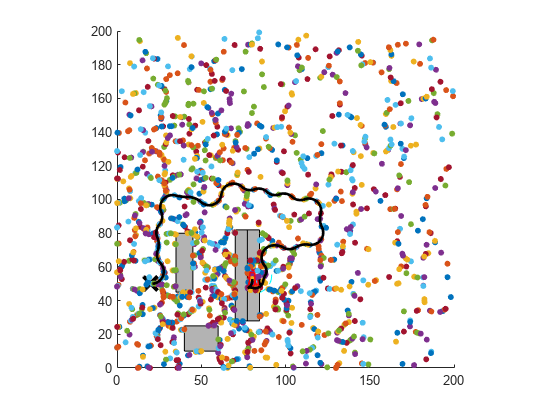

plot(line_array(:,1),line_array(:,2), 'k','LineWidth',2);

function yn = IsObstacle(x,y,obstacle1,obstacle2,obstacle3,obstacle4,obstacle5,x_min,x_max,y_min,y_max)
%check if center point is in obstacle or outside of map
    yn = 0;
    if x>obstacle1(1) && x<(obstacle1(1)+obstacle1(3)) && y>obstacle1(2) && y<(obstacle1(2)+obstacle1(4))
        yn = 1;
        return;
    elseif x>obstacle2(1) && x<(obstacle2(1)+obstacle2(3)) && y>obstacle2(2) && y<(obstacle2(2)+obstacle2(4))
        yn = 1;
        return;
    elseif x>obstacle3(1) && x<(obstacle3(1)+obstacle3(3)) && y>obstacle3(2) && y<(obstacle3(2)+obstacle3(4))
        yn = 1;
        return;
    elseif x>obstacle4(1) && x<(obstacle4(1)+obstacle4(3)) && y>obstacle4(2) && y<(obstacle4(2)+obstacle4(4))
        yn = 1;
        return;
    elseif x>obstacle5(1) && x<(obstacle5(1)+obstacle5(3)) && y>obstacle5(2) && y<(obstacle5(2)+obstacle5(4))
        yn = 1;
        return;
    elseif x<x_min || x>x_max || y<y_min || y>y_max
        yn = 1;
        return;
    end
end

function wn = IsInParking(x1,y1,x2,y2,x3,y3,x4,y4,X0,X1,Y0,Y1)
%check if four corners of car are within parking space
    wn = 0;
    if (x1>X0 && x1<X1 && y1>Y0 && y1<Y1) && (x2>X0 && x2<X1 && y2>Y0 && y2<Y1) && (x3>X0 && x3<X1 && y3>Y0 && y3<Y1) && (x4>X0 && x4<X1 && y4>Y0 && y4<Y1)
        wn = 1;
    end
end